### Universidad del Valle de Guatemala.

#### IE3032 - Procesamiento de Señales.

#### Parcial 1 - Ciclo 1 2022.

Por favor coloque sus datos:

clear;
nombre = 'Cristhofer Isaac Patzan Martinez'; % nombre completo
seccion = 20; % únicas opciones 10 o 20
% 10 (BM-lunes-16:30, IEMT-miércoles-16:30)
% 20 (IEMT-miércoles-14:00)
carnet = 19218;

**Sección I: **Preguntas de selección múltiple en Canvas (3.125/100 puntos c/u).

**Sección II:** Resuelva los problemas que se le presentan a continuación. Debe subir al espacio correspondiente en Canvas un .pdf detallando el procedimiento que empleó para llegar a la respuesta junto con el archivo de respuestas que se generará al final de este documento. Utilice 2 cifras decimales para sus respuestas y procure evaluar las expresiones hasta el final, dado que el calificador empleará las expresiones simbólicas exactas para la comparación. (25/100 puntos c/u, 10 por respuesta correcta y 15 por procedimiento)

1) Determine, desde la definición, la transformada Z de la señal $x\left\lbrack n\right\rbrack =$

p1 = ie3032p1_question(carnet, 1);
disp(p1.expr)

$$-{\left(\frac{91}{100}\right)}^{n-1}\,u\left(n\right)$$

Respuesta:

syms z
X(z) = -(100/90)*( z/( z-(91/100) ) );

2) Emplee el procedimiento de 7 pasos para encontrar y graficar la salida del sistema con respuesta impulsional $h\left\lbrack n\right\rbrack =$

p2 = ie3032p1_question(carnet, 2);
disp(p2.expr)

$$u\left(n\right)$$

si la entrada al mismo es la señal $x\left\lbrack n\right\rbrack =$

disp(p2.expr2)

$$u\left(-n\right)\,{\mathrm{e}}^{\frac{2\,n}{5}-\frac{4}{5}}$$

en el intervalo $-4\le n\le 5$.

Respuesta:

% n =  -4  -3  -2  -1   0   1   2   3   4   5
y=[0.09, 0.23, 0.43, 0.73, 1.78, 1.78, 1.78, 1.78, 1.78, 1.78];

3) Suponga que está comunicando a dos dispositivos digitales mediante una comunicación serial TTL ([https://learn.sparkfun.com/tutorials/serial-communication/all#wiring-and-hardware](https://learn.sparkfun.com/tutorials/serial-communication/all#wiring-and-hardware)):

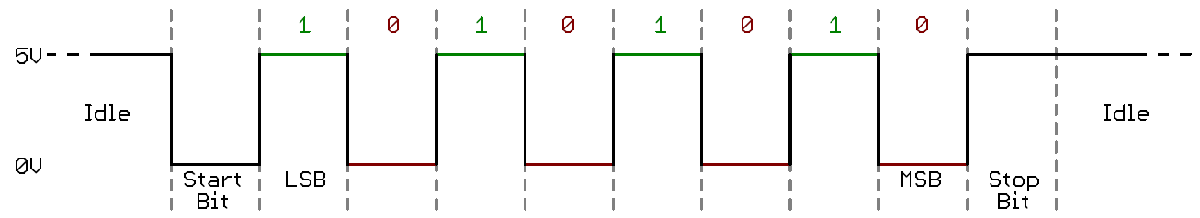 

El emisor envía un comando de 1 byte (8 bits) al receptor, el cual debe ejecutar una acción específica dependiendo del comando recibido. Desafortunadamente, el entorno en donde se encuentran los dispositivos presenta altas cantidades de interferencia electromagnética, por lo que el comando recibido siempre presenta ruido (la ventaja es que todos los comandos presentan el mismo tipo de ruido). Se presenta uno de los comandos recibidos en **cmd_noise.mat** (xcmd contiene la señal y ncmd los valores de tiempo discreto) y, adicionalmente, se visualiza a la derecha. 

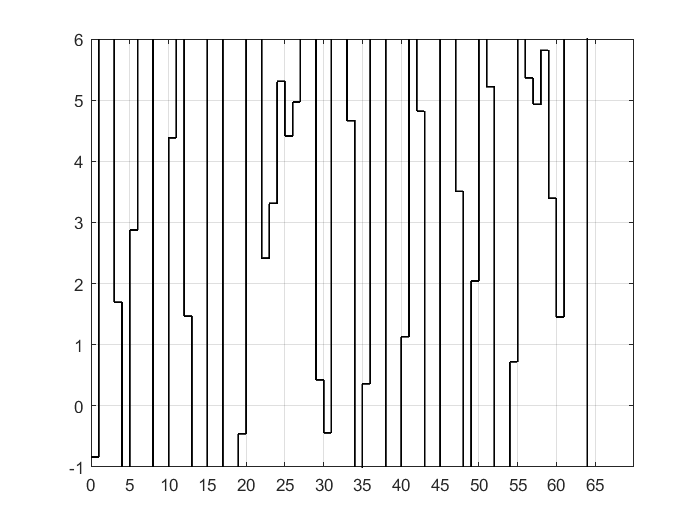

ie3032p1_question(carnet, 3);

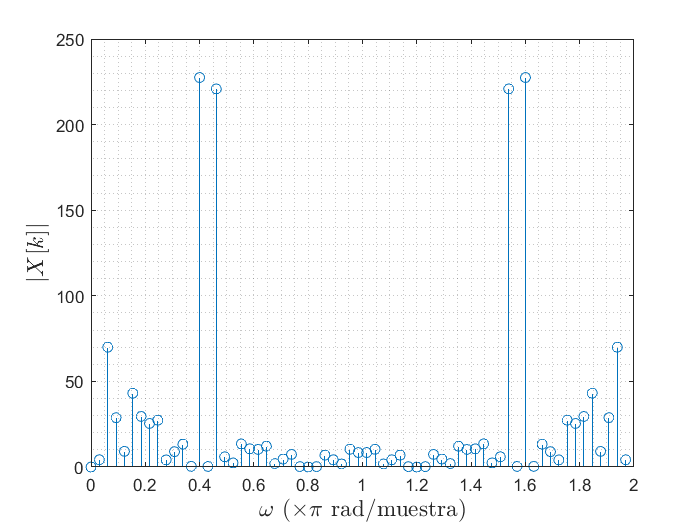


load cmd_noise.mat    % xcmd-->señal , ncmd --> tiempo discreto

%transformo las señales y veo el largo
x_xcmd_centrada = xcmd - mean(xcmd);

x_noisy = fft(x_xcmd_centrada);
N = length(x_noisy);

%db = mag2db(abs(x_noisy));
k = 0:N-1;
dw = 2*pi/N; % Frecuencias armónicas
f_discreta = k*dw/pi; %normalizada k*dw/pi (x pi rad/muestra)

figure(3)
stem(f_discreta, abs(x_noisy));
grid minor;
ylabel('$\left|X[k]\right|$', 'FontSize', 14, 'interpreter', 'latex');
xlabel('$\omega \ (\times \pi \ \mathrm{ rad/}\mathrm{muestra})$', 'FontSize', 14,'interpreter', 'latex');

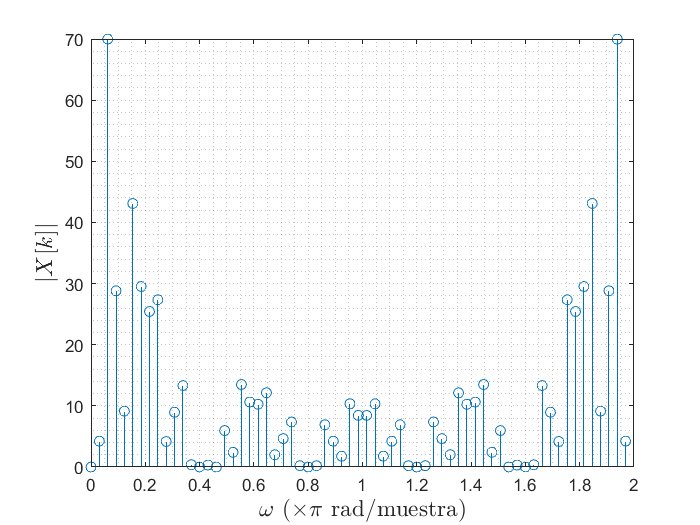


%dB = -254.7   rad/muestra = 0.8
%dB = -254.7   rad/muestra = 1.2
%magnitud = 220

for lugar = 1:N
    if (abs(x_noisy(lugar)) > 200 )
       x_noisy(lugar) = 0;
    end    
end

figure(4)
stem(f_discreta, abs(x_noisy));
grid minor;
ylabel('$\left|X[k]\right|$', 'FontSize', 14, 'interpreter', 'latex');
xlabel('$\omega \ (\times \pi \ \mathrm{ rad/}\mathrm{muestra})$', 'FontSize', 14,'interpreter', 'latex');

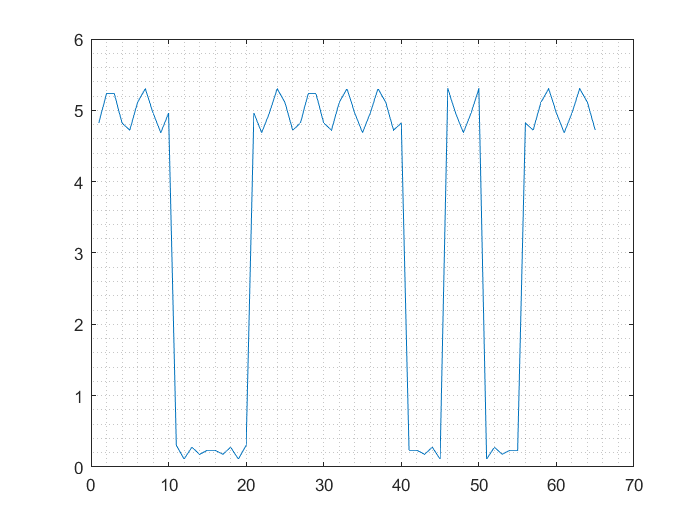


resultante = ifft(x_noisy) + mean(xcmd);


figure(5)
plot(abs(resultante));
grid minor;

Tomando en consideración que el receptor tiene suficientes prestaciones como para calcular la FFT, ¿Cuál fue el comando enviado? Coloque su respuesta, bit por bit (1 o 0), en el siguiente array.

Respuesta:

cmd = [1, 0, 1, 1, 1, 0, 1, 1];

% Se colectan y guardan las respuestas
save('respuestas.mat');

Para finalizar con el examen, ejecute una última vez el código en este documento y ciérrelo guardando los cambios. Desde la línea de comando de MATLAB, ejecute una única vez el comando **submit**, el cual generará un archivo de extensión .submit el cual deberá subir al espacio correspondiente en Canvas junto con los scans de su procedimiento. **NOTA:** el comando submit eliminará de su computadora todos los archivos asociados al examen parcial, por lo que luego de ejecutarlo no se puede revertir. Asegúrese de haber terminado con su examen antes de ejecutar este comando.